format long 
syms f_d(s,t)
% where s = x and y = y

% set the step size 
h = 0.1;
% set the range of points to step through
x = 0:h:2;

% input the derrivative function in to be solved
f_d(s,t) = -1.2*t + 7*exp(-0.3*s);

% create the list of points and put in the initial condition y = 3
y = zeros(length(x),1);
y(1) = 3;

% compute the runge kutta-4
% for i=1:length(y)-1
%     k1 = f_d(x(i),y(i));
%     k2 = f_d(x(i)+h/2,y(i)+k1*h/2);
%     k3 = f_d(x(i)+h/2,y(i)+k2*h/2);
%     k4 = f_d(x(i)+h,y(i)+k3*h);
%     
%     y(i+1) = y(i) + h*(k1+2*k2+2*k3+k4)/6;
% end

for i=1:length(y)-1
    k1 = f_d(x(i),y(i));
    k2 = f_d(x(i)+h,y(i)+k1*h);
    
    y(i+1) = y(i) + h*(k1+k2)/2;
end
y

y =    3.000000000000000
   3.309255936741978
   3.564486678164910
   3.772351972056787
   3.938743627523325
   4.068872632596348
   4.167346430372343
   4.238237464230580
   4.285143977397482
   4.311243940973443


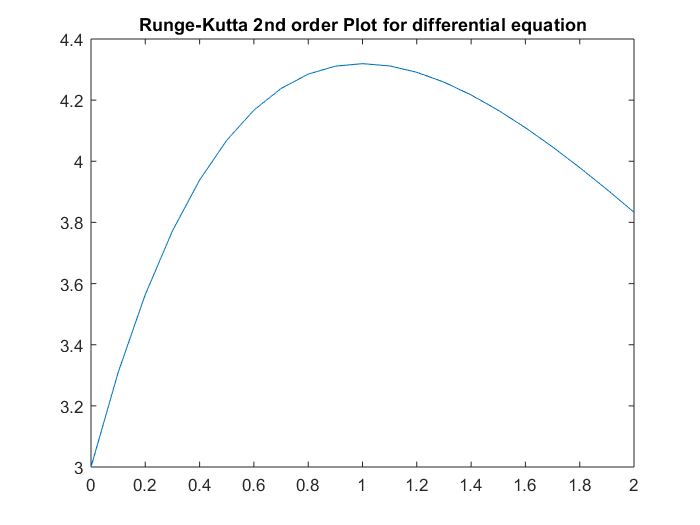

plot(x,y)
title('Runge-Kutta 2nd order Plot for differential equation')